# Flash Spatial Correlations - Voltage Clamp Recordings

ups = grabFromFilter('UP Cells');
downs = grabFromFilter('DOWN Cells');

%choose which protocols to look at
priorityOrder_1 = {'Flash'}; %first field name should be one of these. Priority is in given order
priorityOrder_2 = {'_ff'; 'Intracellular'}; %child field name should be one of these. Priority is in given order
mustHave_1 = [];
mustHave_2 = {'Intracellular', 'Excitation'};
mustHave_2b = {'Intracellular', 'Inhibition'};
cantHave_1 = [];
cantHave_2 = {'Extracellular', 'CurrentClamp'}; %avoid anything with these tags
rigMandates = []; %

coords_up = [];
peakExc_up = [];
ttpExc_up = [];
peakInh_up = [];
ttpInh_up = [];
excTraces_up = zeros(0, 3000);
inhTraces_up = zeros(0, 3000);
for i = 1:size(ups, 1)
    struct_i = ups{i, 2};

    [loc_exc, pass] = getLoc(struct_i, priorityOrder_1, mustHave_1, cantHave_1, priorityOrder_2, mustHave_2, cantHave_2, rigMandates);
    [loc_inh, pass2] = getLoc(struct_i, priorityOrder_1, mustHave_1, cantHave_1, priorityOrder_2, mustHave_2b, cantHave_2, rigMandates);
    
    if pass || pass2
        continue
    end
    
    preTime_i = loc_exc.meta.preTime;
    stimTime_i = loc_exc.meta.stimTime;
    tailTime_i = loc_exc.meta.tailTime;
    
    totalTime = preTime_i + stimTime_i + tailTime_i;
    
    if totalTime ~= 3000
        continue
    end
    
    try
        [x, y] =  pol2cart(struct_i.coordinates.polar(1), struct_i.coordinates.polar(2));
        coords_up = [coords_up; x, y];
    catch
        disp(struct_i.cellID)
        continue
    end

    peakExc_up(end+1, 1) = mean(loc_exc.Analysis_Results.ON_maxNegativePeakByEpoch);
    ttpExc_up(end+1, 1) = mean(loc_exc.Analysis_Results.ON_maxNegativePeakByEpoch_timesToPeak);
    excTraces_up = [excTraces_up; loc_exc.Analysis_Results.meanTrace.meanTrace];
    
    peakInh_up(end+1, 1) = mean(loc_inh.Analysis_Results.ON_maxPositivePeakByEpoch);
    ttpInh_up(end+1, 1) = mean(loc_inh.Analysis_Results.ON_maxPositivePeakByEpoch_timesToPeak);
    inhTraces_up = [inhTraces_up; loc_inh.Analysis_Results.meanTrace.meanTrace];
end


coords_down = [];
peakExc_down = [];
ttpExc_down = [];
peakInh_down = [];
ttpInh_down = [];
excTraces_down = zeros(0, 3000);
inhTraces_down = zeros(0, 3000);
for i = 1:size(downs, 1)
    struct_i = downs{i, 2};

    [loc_exc, pass] = getLoc(struct_i, priorityOrder_1, mustHave_1, cantHave_1, priorityOrder_2, mustHave_2, cantHave_2, rigMandates);
    [loc_inh, pass2] = getLoc(struct_i, priorityOrder_1, mustHave_1, cantHave_1, priorityOrder_2, mustHave_2b, cantHave_2, rigMandates);
    
    if pass || pass2
        continue
    end
    
    preTime_i = loc_exc.meta.preTime;
    stimTime_i = loc_exc.meta.stimTime;
    tailTime_i = loc_exc.meta.tailTime;
    
    totalTime = preTime_i + stimTime_i + tailTime_i;
    
    if totalTime ~= 3000
        continue
    end
    
    try
        [x, y] =  pol2cart(struct_i.coordinates.polar(1), struct_i.coordinates.polar(2));
        coords_down = [coords_down; x, y];
    catch
        disp(struct_i.cellID)
        continue
    end

    peakExc_down(end+1, 1) = mean(loc_exc.Analysis_Results.ON_maxNegativePeakByEpoch);
    ttpExc_down(end+1, 1) = mean(loc_exc.Analysis_Results.ON_maxNegativePeakByEpoch_timesToPeak);
    excTraces_down = [excTraces_down; loc_exc.Analysis_Results.meanTrace.meanTrace];
    
    peakInh_down(end+1, 1) = mean(loc_inh.Analysis_Results.ON_maxPositivePeakByEpoch);
    ttpInh_down(end+1, 1) = mean(loc_inh.Analysis_Results.ON_maxPositivePeakByEpoch_timesToPeak);
    inhTraces_down = [inhTraces_down; loc_inh.Analysis_Results.meanTrace.meanTrace];
end


## Partition based on quadrant of each recorded cell

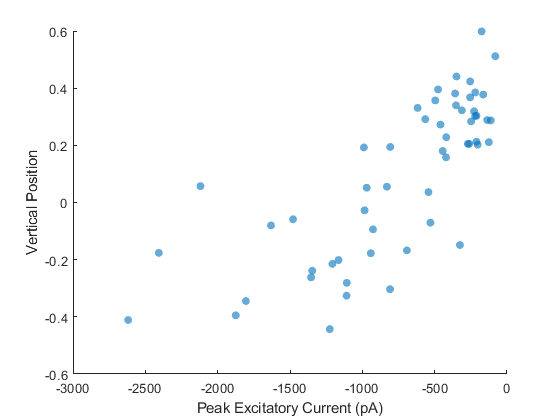

xCoords_up = -coords_up(:, 1); %make x coordinates negative because the manipulator gives opposite x coordinates on rig E
yCoords_up = coords_up(:, 2);
xCoords_down = -coords_down(:, 1);
yCoords_down = coords_down(: , 2);

%store indices of each cell
dt_up = xCoords_up > 0 & yCoords_up > 0;
dt_down = xCoords_down > 0 & yCoords_down > 0;
dn_up = xCoords_up < 0 & yCoords_up > 0;
dn_down = xCoords_down < 0 & yCoords_down > 0;
vn_up = xCoords_up < 0 & yCoords_up < 0;
vn_down = xCoords_down < 0 & yCoords_down < 0;
vt_up = xCoords_up > 0 & yCoords_up < 0;
vt_down = xCoords_down > 0 & yCoords_down < 0;

all_verts = [yCoords_up; yCoords_down];

allPeaks_Ex = [peakExc_up; peakExc_down];
figure
title('Peak Excitatory Current vs Vertical Position')
scatter(allPeaks_Ex, all_verts, 'filled', 'MarkerFaceAlpha', 0.6)
xlabel('Peak Excitatory Current (pA)')
ylabel('Vertical Position')

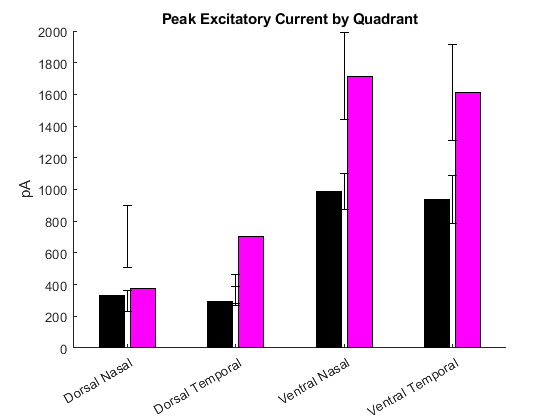

%Magnitude of peak excitation and inhibition by quadrant
dt_upPeakExc = peakExc_up(dt_up);
dn_upPeakExc = peakExc_up(dn_up);
vn_upPeakExc = peakExc_up(vn_up);
vt_upPeakExc = peakExc_up(vt_up);

dt_downPeakExc = peakExc_down(dt_down);
dn_downPeakExc = peakExc_down(dn_down);
vn_downPeakExc = peakExc_down(vn_down);
vt_downPeakExc = peakExc_down(vt_down);

barData = -[mean(dt_upPeakExc), mean(dt_downPeakExc); mean(dn_upPeakExc), mean(dn_downPeakExc); mean(vn_upPeakExc), mean(vn_downPeakExc); mean(vt_upPeakExc), mean(vt_downPeakExc)];
SE_F = @(d) std(d)./sqrt(size(d, 1));
barError = [SE_F(dt_upPeakExc), SE_F(dt_downPeakExc); SE_F(dn_upPeakExc), SE_F(dn_downPeakExc); SE_F(vn_upPeakExc), SE_F(vn_downPeakExc); SE_F(vt_upPeakExc), SE_F(vt_downPeakExc)];

figure
title('Peak Excitatory Current by Quadrant')
hold on
ylabel('pA')
x = categorical({'Dorsal Temporal', 'Dorsal Nasal', 'Ventral Nasal', 'Ventral Temporal'});
b = bar(x, barData);
b(1).FaceColor = 'k';
b(2).FaceColor = 'm';

% Plot the errorbars
errorbar(barData,barError,'k','linestyle','none');
hold off

%p value for all ventral vs all dorsal (irrespective of cell type)
p = ranksum([vn_downPeakExc; vn_upPeakExc; vt_downPeakExc; vt_upPeakExc], [dn_downPeakExc; dn_upPeakExc; dt_downPeakExc; dt_upPeakExc])

p = 2.1294e-07

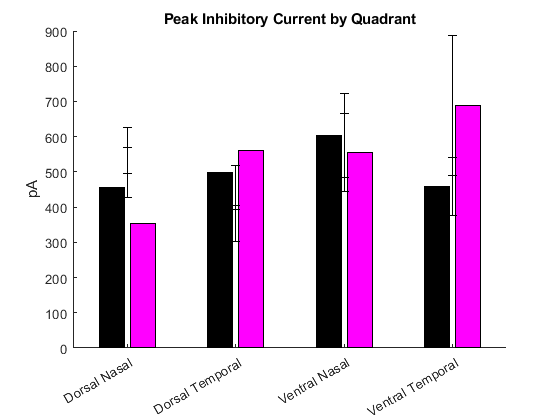

%Repeat for inhibition
dt_upPeakInh = peakInh_up(dt_up);
dn_upPeakInh = peakInh_up(dn_up);
vn_upPeakInh = peakInh_up(vn_up);
vt_upPeakInh = peakInh_up(vt_up);

dt_downPeakInh = peakInh_down(dt_down);
dn_downPeakInh = peakInh_down(dn_down);
vn_downPeakInh = peakInh_down(vn_down);
vt_downPeakInh = peakInh_down(vt_down);


barData = [mean(dt_upPeakInh), mean(dt_downPeakInh); mean(dn_upPeakInh), mean(dn_downPeakInh); mean(vn_upPeakInh), mean(vn_downPeakInh); mean(vt_upPeakInh), mean(vt_downPeakInh)];
barError = -[SE_F(dt_upPeakInh), SE_F(dt_downPeakInh); SE_F(dn_upPeakInh), SE_F(dn_downPeakInh); SE_F(vn_upPeakInh), SE_F(vn_downPeakInh); SE_F(vt_upPeakInh), SE_F(vt_downPeakInh)];

figure
title('Peak Inhibitory Current by Quadrant')
hold on
ylabel('pA')
x = categorical({'Dorsal Temporal', 'Dorsal Nasal', 'Ventral Nasal', 'Ventral Temporal'});
b = bar(x, barData);
b(1).FaceColor = 'k';
b(2).FaceColor = 'm';

% Plot the errorbars
errorbar(barData,barError,'k','linestyle','none');
hold off

p = ranksum([vn_downPeakInh; vn_upPeakInh; vt_downPeakInh; vt_upPeakInh], [dn_downPeakInh; dn_upPeakInh; dt_downPeakInh; dt_upPeakInh])

p = 0.2376

## Mean Traces

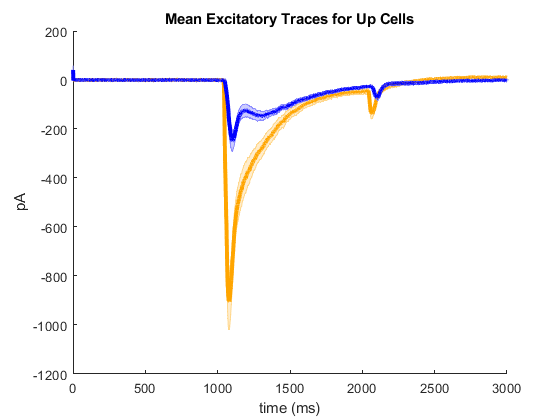

Ventral_Up_MeanExc = excTraces_up(vt_up | vn_up, :);
Dorsal_Up_MeanExc = excTraces_up(dt_up | dn_up, :);

timeAxis = [1:size(excTraces_up, 2)];
figure
title('Mean Excitatory Traces for Up Cells')
hold on
shadedErrorBar(timeAxis, mean(Ventral_Up_MeanExc), SE_F(Ventral_Up_MeanExc), 'lineprops', {'color', [255, 165, 0]/255, 'linewidth', 3})
shadedErrorBar(timeAxis, mean(Dorsal_Up_MeanExc), SE_F(Dorsal_Up_MeanExc), 'lineprops', {'color', [0, 0, 255]/255, 'linewidth', 3})
xlabel('time (ms)')
ylabel('pA')

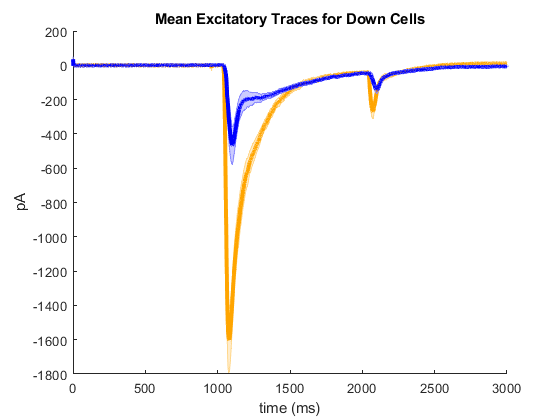

Ventral_Down_MeanExc = excTraces_down(vt_down | vn_down, :);
Dorsal_Down_MeanExc = excTraces_down(dt_down | dn_down, :);

timeAxis = [1:size(excTraces_down, 2)];
figure
title('Mean Excitatory Traces for Down Cells')
hold on
shadedErrorBar(timeAxis, mean(Ventral_Down_MeanExc), SE_F(Ventral_Down_MeanExc), 'lineprops', {'color', [255, 165, 0]/255, 'linewidth', 3})
shadedErrorBar(timeAxis, mean(Dorsal_Down_MeanExc), SE_F(Dorsal_Down_MeanExc), 'lineprops', {'color', [0, 0, 255]/255, 'linewidth', 3})
xlabel('time (ms)')
ylabel('pA')

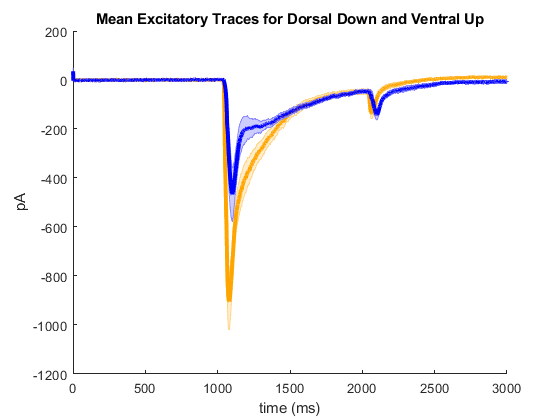

timeAxis = [1:size(excTraces_down, 2)];

figure
title('Mean Excitatory Traces for Dorsal Down and Ventral Up')
hold on
shadedErrorBar(timeAxis, mean(Ventral_Up_MeanExc), SE_F(Ventral_Up_MeanExc), 'lineprops', {'color', [255, 165, 0]/255, 'linewidth', 3})
shadedErrorBar(timeAxis, mean(Dorsal_Down_MeanExc), SE_F(Dorsal_Down_MeanExc), 'lineprops', {'color', [0, 0, 255]/255, 'linewidth', 3})
xlabel('time (ms)')
ylabel('pA')

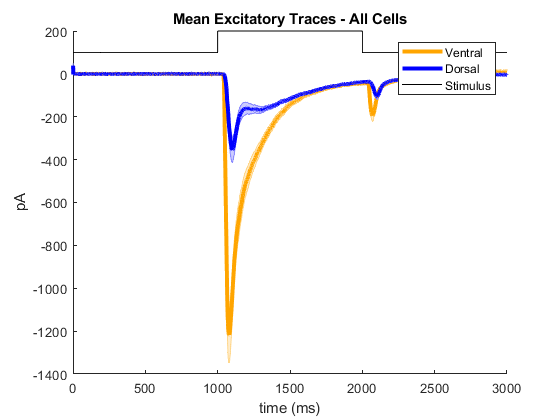

figure
title('Mean Excitatory Traces - All Cells')
hold on
shadedErrorBar(timeAxis, mean([Ventral_Up_MeanExc; Ventral_Down_MeanExc]), SE_F([Ventral_Up_MeanExc; Ventral_Down_MeanExc]), 'lineprops', {'color', [255, 165, 0]/255, 'linewidth', 3})
shadedErrorBar(timeAxis, mean([Dorsal_Up_MeanExc; Dorsal_Down_MeanExc]), SE_F([Dorsal_Up_MeanExc; Dorsal_Down_MeanExc]), 'lineprops', {'color', [0, 0, 255]/255, 'linewidth', 3})
plot([0 1000 1000 2000 2000 3000], [100 100 200 200 100 100], '-k')
xlabel('time (ms)')
ylabel('pA')
legend('Ventral', 'Dorsal', 'Stimulus')

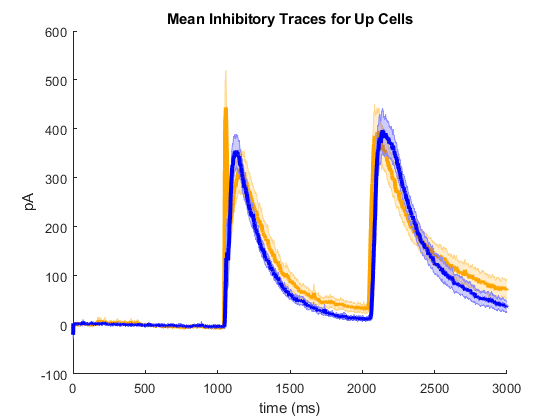


Ventral_Up_MeanInh = inhTraces_up(vt_up | vn_up, :);
Dorsal_Up_MeanInh = inhTraces_up(dt_up | dn_up, :);

timeAxis = [1:size(inhTraces_up, 2)];
figure
title('Mean Inhibitory Traces for Up Cells')
hold on
shadedErrorBar(timeAxis, mean(Ventral_Up_MeanInh), SE_F(Ventral_Up_MeanInh), 'lineprops', {'color', [255, 165, 0]/255, 'linewidth', 3})
shadedErrorBar(timeAxis, mean(Dorsal_Up_MeanInh), SE_F(Dorsal_Up_MeanInh), 'lineprops', {'color', [0, 0, 255]/255, 'linewidth', 3})
xlabel('time (ms)')
ylabel('pA')

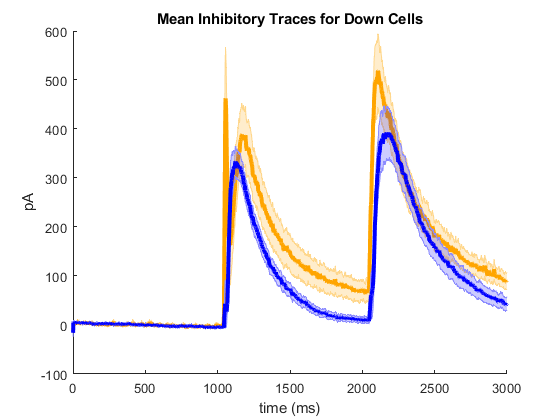

Ventral_Down_MeanInh = inhTraces_down(vt_down | vn_down, :);
Dorsal_Down_MeanInh = inhTraces_down(dt_down | dn_down, :);

timeAxis = [1:size(inhTraces_down, 2)];
figure
title('Mean Inhibitory Traces for Down Cells')
hold on
shadedErrorBar(timeAxis, mean(Ventral_Down_MeanInh), SE_F(Ventral_Down_MeanInh), 'lineprops', {'color', [255, 165, 0]/255, 'linewidth', 3})
shadedErrorBar(timeAxis, mean(Dorsal_Down_MeanInh), SE_F(Dorsal_Down_MeanInh), 'lineprops', {'color', [0, 0, 255]/255, 'linewidth', 3})
xlabel('time (ms)')
ylabel('pA')

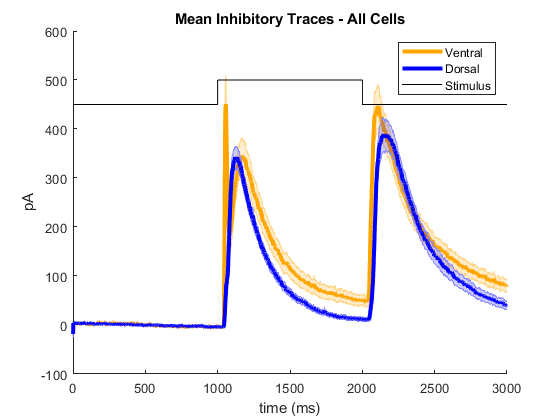

figure
title('Mean Inhibitory Traces - All Cells')
hold on
shadedErrorBar(timeAxis, mean([Ventral_Up_MeanInh; Ventral_Down_MeanInh]), SE_F([Ventral_Up_MeanInh; Ventral_Down_MeanInh]), 'lineprops', {'color', [255, 165, 0]/255, 'linewidth', 3})
shadedErrorBar(timeAxis, mean([Dorsal_Up_MeanInh; Dorsal_Down_MeanInh]), SE_F([Dorsal_Up_MeanInh; Dorsal_Down_MeanInh]), 'lineprops', {'color', [0, 0, 255]/255, 'linewidth', 3})
plot([0 1000 1000 2000 2000 3000], [450 450 500 500 450 450], '-k')
xlabel('time (ms)')
ylabel('pA')
legend('Ventral', 'Dorsal', 'Stimulus')

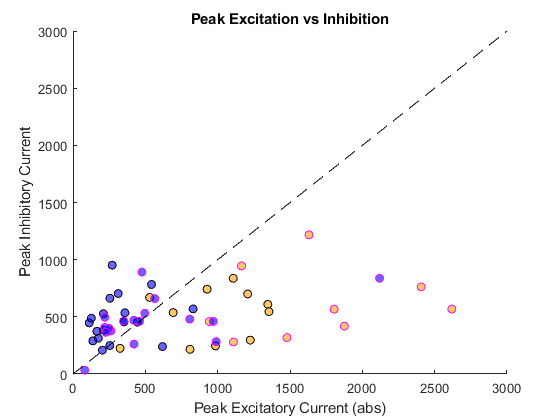

peakInh_dorsal_Up = [dt_upPeakInh; dn_upPeakInh];
peakInh_dorsal_Down = [dt_downPeakInh;dn_downPeakInh];
peakInh_ventral_Up = [vt_upPeakInh; vn_upPeakInh];
peakInh_ventral_Down = [vt_downPeakInh; vn_downPeakInh];
peakExc_dorsal_Up = [dt_upPeakExc; dn_upPeakExc];
peakExc_dorsal_Down = [dt_downPeakExc;dn_downPeakExc];
peakExc_ventral_Up = [vt_upPeakExc; vn_upPeakExc];
peakExc_ventral_Down = [vt_downPeakExc; vn_downPeakExc];

figure
title('Peak Excitation vs Inhibition')
hold on
scatter(-peakExc_ventral_Up, peakInh_ventral_Up, 'filled', 'MarkerFaceColor', [255, 165, 0]/255, 'MarkerFaceAlpha', 0.6, 'MarkerEdgeColor','k')
scatter(-peakExc_ventral_Down, peakInh_ventral_Down, 'filled', 'MarkerFaceColor', [255, 165, 0]/255, 'MarkerFaceAlpha', 0.6, 'MarkerEdgeColor','m')
scatter(-peakExc_dorsal_Up, peakInh_dorsal_Up, 'filled', 'MarkerFaceColor', [0, 0, 255]/255, 'MarkerFaceAlpha', 0.6, 'MarkerEdgeColor', 'k')
scatter(-peakExc_dorsal_Down, peakInh_dorsal_Down, 'filled', 'MarkerFaceColor', [0, 0, 255]/255, 'MarkerFaceAlpha', 0.6, 'MarkerEdgeColor', 'm')
xlabel('Peak Excitatory Current (abs)')
ylabel('Peak Inhibitory Current')
plot([0 3000], [0 3000], '--k')

p_ventral = signrank(-[peakExc_ventral_Up; peakExc_ventral_Down], [peakInh_ventral_Up; peakInh_ventral_Down])

p_ventral = 1.2042e-04

p_dorsal = signrank(-[peakExc_dorsal_Up; peakExc_dorsal_Down], [peakInh_dorsal_Up; peakInh_dorsal_Down])

p_dorsal = 0.0619

p_ranksumEI = ranksum(-[peakExc_ventral_Up; peakExc_ventral_Down]./[peakInh_ventral_Up; peakInh_ventral_Down], -[peakExc_dorsal_Up; peakExc_dorsal_Down]./[peakInh_dorsal_Up; peakInh_dorsal_Down])

p_ranksumEI = 2.8649e-06

## Time to peak

Ventral_Up_ttpExc = ttpExc_up(vt_up | vn_up)-1000; %subtract 1000ms from ttp to get rid of the pretime
Dorsal_Up_ttpExc = ttpExc_up(dt_up | dn_up)-1000;

Ventral_Down_ttpExc = ttpExc_down(vt_down | vn_down)-1000;
Dorsal_Down_ttpExc = ttpExc_down(dt_down | dn_down)-1000;


allPoints = [Ventral_Up_ttpExc; Dorsal_Up_ttpExc; Ventral_Down_ttpExc; Dorsal_Down_ttpExc];
groupIDs = zeros(1, numel(allPoints));
indx1 = numel(Ventral_Up_ttpExc); indx2 = numel(Ventral_Up_ttpExc) + numel(Dorsal_Up_ttpExc);
indx3 = numel(Ventral_Up_ttpExc) + numel(Dorsal_Up_ttpExc) + numel(Ventral_Down_ttpExc);
groupIDs(indx1 + 1:indx2) = 1;
groupIDs(indx2 + 1:indx3) = 2;
groupIDs(indx3 + 1:end) = 3;


figure
title ('Time to Peak Excitatory Current')
hold on
boxplot(allPoints, groupIDs, 'Symbol' , '', 'Widths', 0.5)
scatter(ones(1, numel(Ventral_Up_ttpExc)), Ventral_Up_ttpExc,'filled', 'MarkerFaceColor', [255, 165, 0]/255, 'MarkerFaceAlpha', 0.6, 'XJitter','density', 'XJitterWidth', 0.5)
scatter(ones(1, numel(Dorsal_Up_ttpExc))+1, Dorsal_Up_ttpExc,'filled', 'MarkerFaceColor', [0, 0, 255]/255, 'MarkerFaceAlpha',0.6, 'XJitter','density', 'XJitterWidth', 0.5)
scatter(ones(1, numel(Ventral_Down_ttpExc))+2, Ventral_Down_ttpExc,'filled','MarkerFaceColor', [255, 165, 0]/255, 'MarkerFaceAlpha', 0.6, 'XJitter','density', 'XJitterWidth', 0.5)
scatter(ones(1, numel(Dorsal_Down_ttpExc))+3, Dorsal_Down_ttpExc,'filled', 'MarkerFaceColor', [0, 0, 255]/255, 'MarkerFaceAlpha',0.6, 'XJitter','density', 'XJitterWidth', 0.5)
xticklabels({'Up Ventral', 'Up Dorsal', 'Down Ventral', 'Down Dorsal'})
ylabel('ms')
box off

p_up = ranksum(Ventral_Up_ttpExc, Dorsal_Up_ttpExc)
p_down = ranksum(Ventral_Down_ttpExc, Dorsal_Down_ttpExc)
allPoints = [Ventral_Up_ttpExc; Ventral_Down_ttpExc; Dorsal_Up_ttpExc; Dorsal_Down_ttpExc];
groupIDs = zeros(1, numel(allPoints));
indx1 = numel(Ventral_Up_ttpExc) + numel(Ventral_Down_ttpExc);
groupIDs(indx1 + 1:end) = 1;

figure
title ('Time to Peak Excitatory Current')
hold on
boxplot(allPoints, groupIDs, 'Symbol' , '', 'Widths', 0.5)
scatter(ones(1, numel([Ventral_Up_ttpExc; Ventral_Down_ttpExc])), [Ventral_Up_ttpExc; Ventral_Down_ttpExc], 'filled', 'MarkerFaceColor', [255, 165, 0]/255, 'MarkerFaceAlpha', 0.6, 'XJitter','density', 'XJitterWidth', 0.5)
scatter(ones(1, numel([Dorsal_Up_ttpExc; Dorsal_Down_ttpExc]))+1, [Dorsal_Up_ttpExc; Dorsal_Down_ttpExc], 'filled', 'MarkerFaceColor', [0, 0, 255]/255, 'MarkerFaceAlpha', 0.6, 'XJitter','density', 'XJitterWidth', 0.5)
xticklabels({'Ventral', 'Dorsal'})
ylabel('ms')
box off
p = ranksum([Ventral_Up_ttpExc; Ventral_Down_ttpExc], [Dorsal_Up_ttpExc; Dorsal_Down_ttpExc])

% Repeat for Inhibition
Ventral_Up_ttpInh = ttpInh_up(vt_up | vn_up)-1000; %subtract 1000ms from ttp to get rid of the pretime
Dorsal_Up_ttpInh = ttpInh_up(dt_up | dn_up)-1000;

Ventral_Down_ttpInh = ttpInh_down(vt_down | vn_down)-1000;
Dorsal_Down_ttpInh = ttpInh_down(dt_down | dn_down)-1000;


allPoints = [Ventral_Up_ttpInh; Dorsal_Up_ttpInh; Ventral_Down_ttpInh; Dorsal_Down_ttpInh];
groupIDs = zeros(1, numel(allPoints));
indx1 = numel(Ventral_Up_ttpInh); indx2 = numel(Ventral_Up_ttpInh) + numel(Dorsal_Up_ttpInh);
indx3 = numel(Ventral_Up_ttpInh) + numel(Dorsal_Up_ttpInh) + numel(Ventral_Down_ttpInh);
groupIDs(indx1 + 1:indx2) = 1;
groupIDs(indx2 + 1:indx3) = 2;
groupIDs(indx3 + 1:end) = 3;


figure
title ('Time to Peak Inhibitory Current')
hold on
boxplot(allPoints, groupIDs, 'Symbol' , '', 'Widths', 0.5)
scatter(ones(1, numel(Ventral_Up_ttpInh)), Ventral_Up_ttpInh,'filled', 'MarkerFaceColor', [255, 165, 0]/255, 'MarkerFaceAlpha', 0.6, 'XJitter','density', 'XJitterWidth', 0.5)
scatter(ones(1, numel(Dorsal_Up_ttpInh))+1, Dorsal_Up_ttpInh,'filled', 'MarkerFaceColor', [0, 0, 255]/255, 'MarkerFaceAlpha',0.6, 'XJitter','density', 'XJitterWidth', 0.5)
scatter(ones(1, numel(Ventral_Down_ttpInh))+2, Ventral_Down_ttpInh,'filled','MarkerFaceColor', [255, 165, 0]/255, 'MarkerFaceAlpha', 0.6, 'XJitter','density', 'XJitterWidth', 0.5)
scatter(ones(1, numel(Dorsal_Down_ttpInh))+3, Dorsal_Down_ttpInh,'filled', 'MarkerFaceColor', [0, 0, 255]/255, 'MarkerFaceAlpha',0.6, 'XJitter','density', 'XJitterWidth', 0.5)
xticklabels({'Up Ventral', 'Up Dorsal', 'Down Ventral', 'Down Dorsal'})
ylabel('ms')
box off
p_up = ranksum(Ventral_Up_ttpInh, Dorsal_Up_ttpInh)
p_down = ranksum(Ventral_Down_ttpInh, Dorsal_Down_ttpInh)
p_total = ranksum([Ventral_Up_ttpInh; Ventral_Down_ttpInh], [Dorsal_Up_ttpInh; Dorsal_Down_ttpInh])
allPoints = [Ventral_Up_ttpInh; Ventral_Down_ttpInh; Dorsal_Up_ttpInh; Dorsal_Down_ttpInh];
groupIDs = zeros(1, numel(allPoints));
indx1 = numel(Ventral_Up_ttpInh) + numel(Ventral_Down_ttpInh);
groupIDs(indx1 + 1:end) = 1;

figure
title ('Time to Peak Inhibitory Current - All Cells')
hold on
boxplot(allPoints, groupIDs, 'Symbol' , '', 'Widths', 0.5)
scatter(ones(1, numel([Ventral_Up_ttpInh; Ventral_Down_ttpInh])), [Ventral_Up_ttpInh; Ventral_Down_ttpInh], 'filled', 'MarkerFaceColor', [255, 165, 0]/255, 'MarkerFaceAlpha', 0.6, 'XJitter','density', 'XJitterWidth', 0.5)
scatter(ones(1, numel([Dorsal_Up_ttpInh; Dorsal_Down_ttpInh]))+1, [Dorsal_Up_ttpInh; Dorsal_Down_ttpInh], 'filled', 'MarkerFaceColor', [0, 0, 255]/255, 'MarkerFaceAlpha', 0.6, 'XJitter','density', 'XJitterWidth', 0.5)
xticklabels({'Ventral', 'Dorsal'})
ylabel('ms')
box off
ylim([0 200])
p = ranksum([Ventral_Up_ttpInh; Ventral_Down_ttpInh], [Dorsal_Up_ttpInh; Dorsal_Down_ttpInh])

## Compare Excitation and Inhibition For Ventral Cells

%What is that first little peak in the inhibition trace for ventral cells?
%Is it from a reversal of the excitatory driving force?

%plot excitation and inhibition together on the same axes
excUp = -mean(Ventral_Up_MeanExc);
excUpNormed = excUp/max(excUp);
inhUp = mean(Ventral_Up_MeanInh);
inhUpNormed = inhUp/max(inhUp);

figure
title('Ventral Up Cells: Excitation vs Inhibition')
hold on
plot(timeAxis, excUp, 'k')
plot(timeAxis, inhUp, 'r')
xlabel('time (ms)')
ylabel('pA')
figure
title('Ventral Up Cells: Excitation vs Inhibition - Max Normalized')
hold on
plot(timeAxis, excUpNormed, 'k')
plot(timeAxis, inhUpNormed, 'r')
xlabel('time (ms)')
ylabel('A.U.')
%Repeat for ventral Down cells
excDown = -mean(Ventral_Down_MeanExc);
excDownNormed = excDown/max(excDown);
inhDown = mean(Ventral_Down_MeanInh);
inhDownNormed = inhDown/max(inhDown);

figure
title('Ventral Down Cells: Excitation vs Inhibition')
hold on
plot(timeAxis, excDown, 'k')
plot(timeAxis, inhDown, 'r')
xlabel('time (ms)')
ylabel('pA')
figure
title('Ventral Down Cells: Excitation vs Inhibition - Max Normalized')
hold on
plot(timeAxis, excDownNormed, 'k')
plot(timeAxis, inhDownNormed, 'r')
xlabel('time (ms)')
ylabel('A.U.')